N = 600;          %主链长度
N1 =300;         %支链1连接位置
N0 =2;           %每个支链长度（不含分支点）
L = 4;            %支链间距（含两端点）
J = 100;            %相互作用强度
loop = true;



%定义哈密顿量
%主链编号为1~N，支链编号为N+1~N+N0,N+N0+1~N+2*N0

H = zeros(N+2*N0, N+2*N0);         %初始化

%主链相互作用
for ii = 1:(N-1)
    H = interaction(H, ii, ii+1);
end
if loop == true
    H = interaction(H, N, 1);
end

%支链相互作用
for ii = 1:N0-1
    H = interaction(H, N+ii, N+ii+1);
    H = interaction(H, N+N0+ii, N+N0+ii+1);
end

%连接处相互作用
H = interaction(H, N1, N+1);
H = interaction(H, N1+L-1, N+N0+1);

%整体乘以相互作用强度
H = -J * H;

%在两端加上轻微的衰减，防止反射
%衰减不能太强，否则会直接反射
for ii = 1:20
    H(ii,ii) = -0.1*J*1i;
end
for ii = (N-70):N
    H(ii,ii) = -0.05*J*1i;
end

[VEC,D] = eig(H);

%计算单个k的粒子透射情况
k = pi/4;
tmax = 500/(1 + 100*k + 9*k.^2) + 2;
NA = 140;
Delta = 100;
psi0 = GaussianState(N+2*N0, NA, k, Delta);
psi0(N+1:N+2*N0) = 0;
%opts = odeset('Reltol', 1e-8, 'AbsTol', 1e-10);
tic
[t1, psi1] = psicalc(H, psi0, tmax, 'eig', 300, VEC, D);
%[t1, psi1] = psicalc(H, psi0, tmax, 'ode', opts);
toc

历时 9.433119 秒。


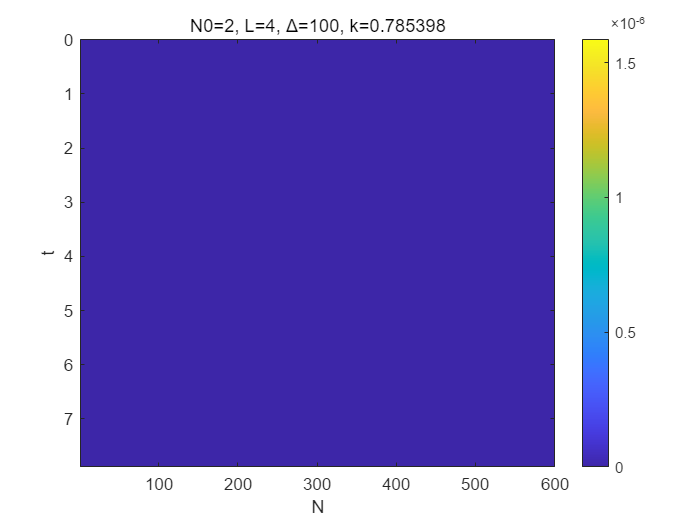

T1 = max(vecnorm(psi1(:, (N1+L+1):N-70), 2, 2))^2;
plotpsi2d(psi1(:,1:N), t1, N)
title(sprintf('N0=%d, L=%d, Δ=%d, k=%f', N0, L, Delta, k))

%计算不同k的粒子透射率
ks = linspace(0, pi/2, 100);
NA = 140;
Delta = 100;
T = zeros(0, length(ks));
tic
parfor ii = 1:length(ks)
    psi0 = GaussianState(N+2*N0, NA, ks(ii), Delta);
    psi0(N+1:N+2*N0) = 0;
    tmax = 500 / (1 + 100*ks(ii) + 9*ks(ii)^2);
    [~, psi] = psicalc(H, psi0, tmax, 'eig', 100, VEC, D)
    T(ii) = max(vecnorm(psi(:, (N1+L+1):N-50), 2, 2))^2;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


toc

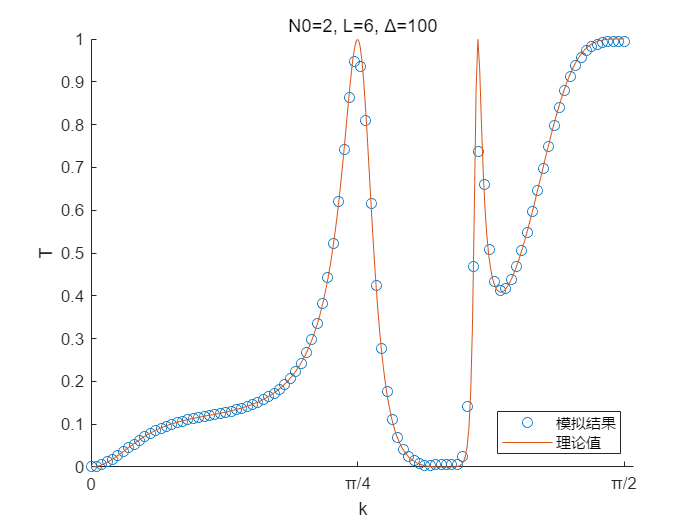

scatter(ks, T);
hold on
x = linspace(0, pi/2, 300);
a = J * sin(x*(N0+1));
b = J * sin(x*N0);
delta = atan(2*a.*sin(x)./b);
numerator = a.^4.*(sin(x).^4);
denominator = a.^4.*(sin(x).^4)+(b./2).^2.*(b.^2+4*a.^2.*sin(x).^2).*sin(x.*(L-1)-delta).^2;
y = numerator./denominator;
plot(x,y)
hold off
xlabel('k')
ylabel('T')
xticks([0 pi/4 pi/2])
xticklabels({'0','\pi/4','\pi/2'})
legend('模拟结果','理论值','Location','southeast')
title(sprintf('N0=%d, L=%d, Δ=%d', N0, L, Delta))

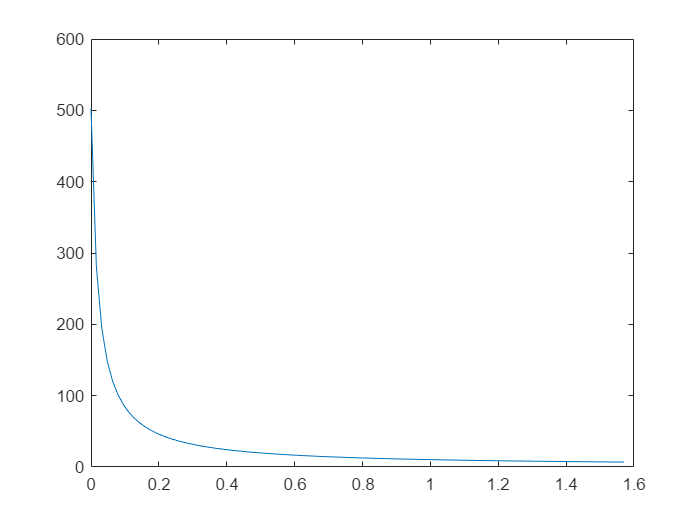

x = linspace(0, pi/2, 100);
y = 500 ./ (1 + 50*x + 9*x.^2) + 2;
plot(x,y)

opts = odeset('Reltol',1e-8,'AbsTol',1e-10);
tspan = [0 tmax];
tic
k = pi*[1/3 1/9 2/9 4/9];
psi = cell(length(k),1);
t = cell(length(k),1);
locations = [(N+N0-(0:N0-1)) N1:(N1+L-1) (N+N0+1):(N+2*N0)];  %按顺序排列的子链粒子
psi0 = initpsi(N,N0,N1,L,k(1));
[t{1},psi{1}] = ode113(@(t,psi) -1i*H*psi, tspan, psi0, opts);
p = vecnorm(psi{1}(:,locations),2,2);        %粒子在选定位置出现概率之和
plot(t{1},p)
hold on
for ii = 2:length(k)
psi0 = initpsi(N,N0,N1,L,k(ii));
[t{ii},psi{ii}] = ode113(@(t,psi) -1i*H*psi, tspan, psi0, opts);
p = vecnorm(psi{ii}(:,locations),2,2);        %粒子在选定位置出现概率之和
plot(t{ii},p)
end
toc

历时 54.172071 秒。


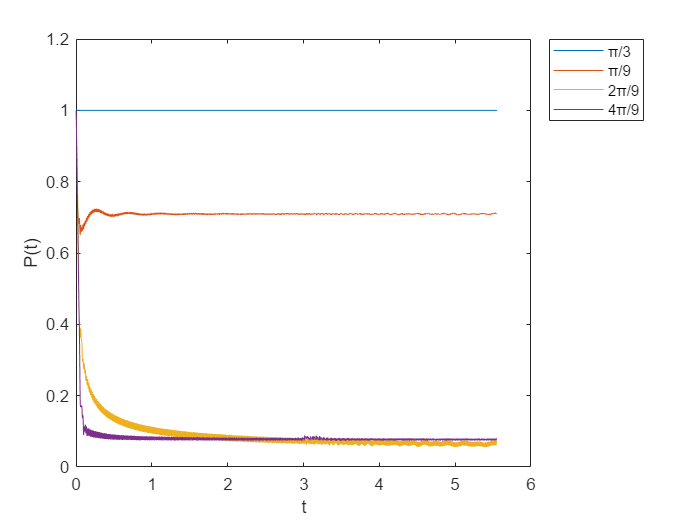

hold off
legend('π/3','π/9','2π/9','4π/9')
%legend('π/2','π/130','16π/65','7π/26')
xlabel('t')
ylabel('P(t)')

%axis([0 100 0.8 1.05])

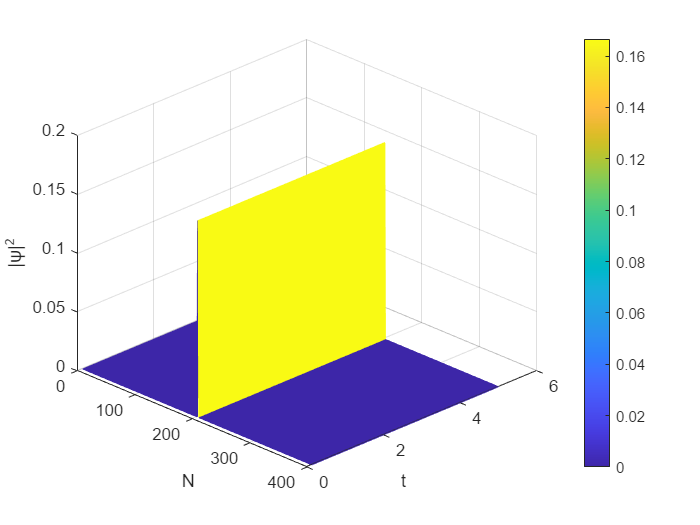

plotpsi(psi{1}(100:end,1:N),t{1}(100:end),N)

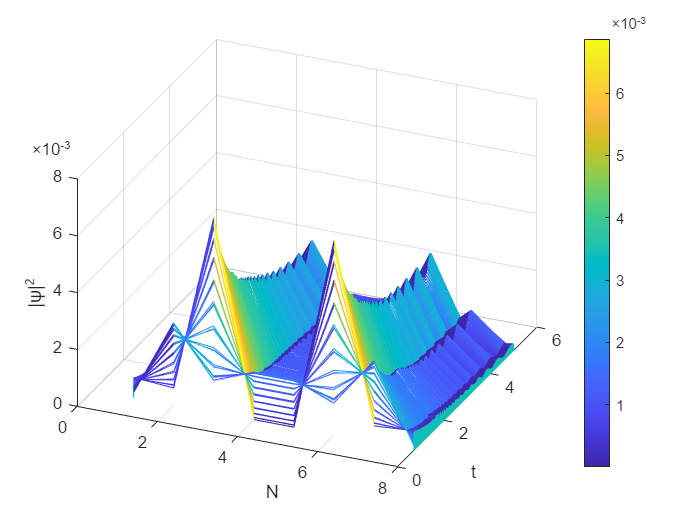

plotpsi(psi{3}(1000:end,locations),t{3}(1000:end),length(locations))

tspan = linspace(0,100,500);
locations = [(N+N0-(0:N0-1)) N1:(N1+L-1) (N+N0+1):(N+2*N0)];  %按顺序排列的子链粒子
psi0 = initpsi(N,N0,N1,L,k(3));
psi = zeros(500,N+2*N0);
tic
ii = 1;
for t = tspan
    psi(ii,:) = transpose(expm(-1i*H*t)*psi0);
    ii = ii + 1;
end
toc

历时 15.697780 秒。


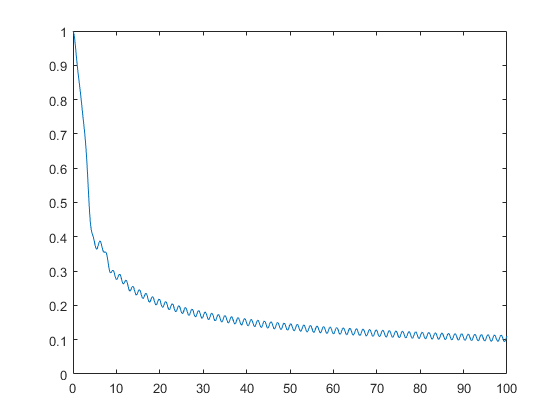

p = vecnorm(psi(:,locations),2,2);        %粒子在选定位置出现概率之和
plot(tspan,p)

function psi0 = initpsi(N, N0, N1, L, k)
Lambda = L + 2 * N0;              %总长度
psi1 = sin(k * (1:Lambda));
psi1 = psi1 / (norm(psi1));
psi0 = zeros(N + 2 * N0,1);
locations = [(N+N0-(0:N0-1)) N1:(N1+L-1) (N+N0+1):(N+2*N0)];  %按顺序排列的子链粒子
psi0(locations) = psi1;
end

